[sectn] = sectn_circularTube(d, t)

sectn_circularTube(d, t) computes the beam section properties for a beam of circular tube cross section.

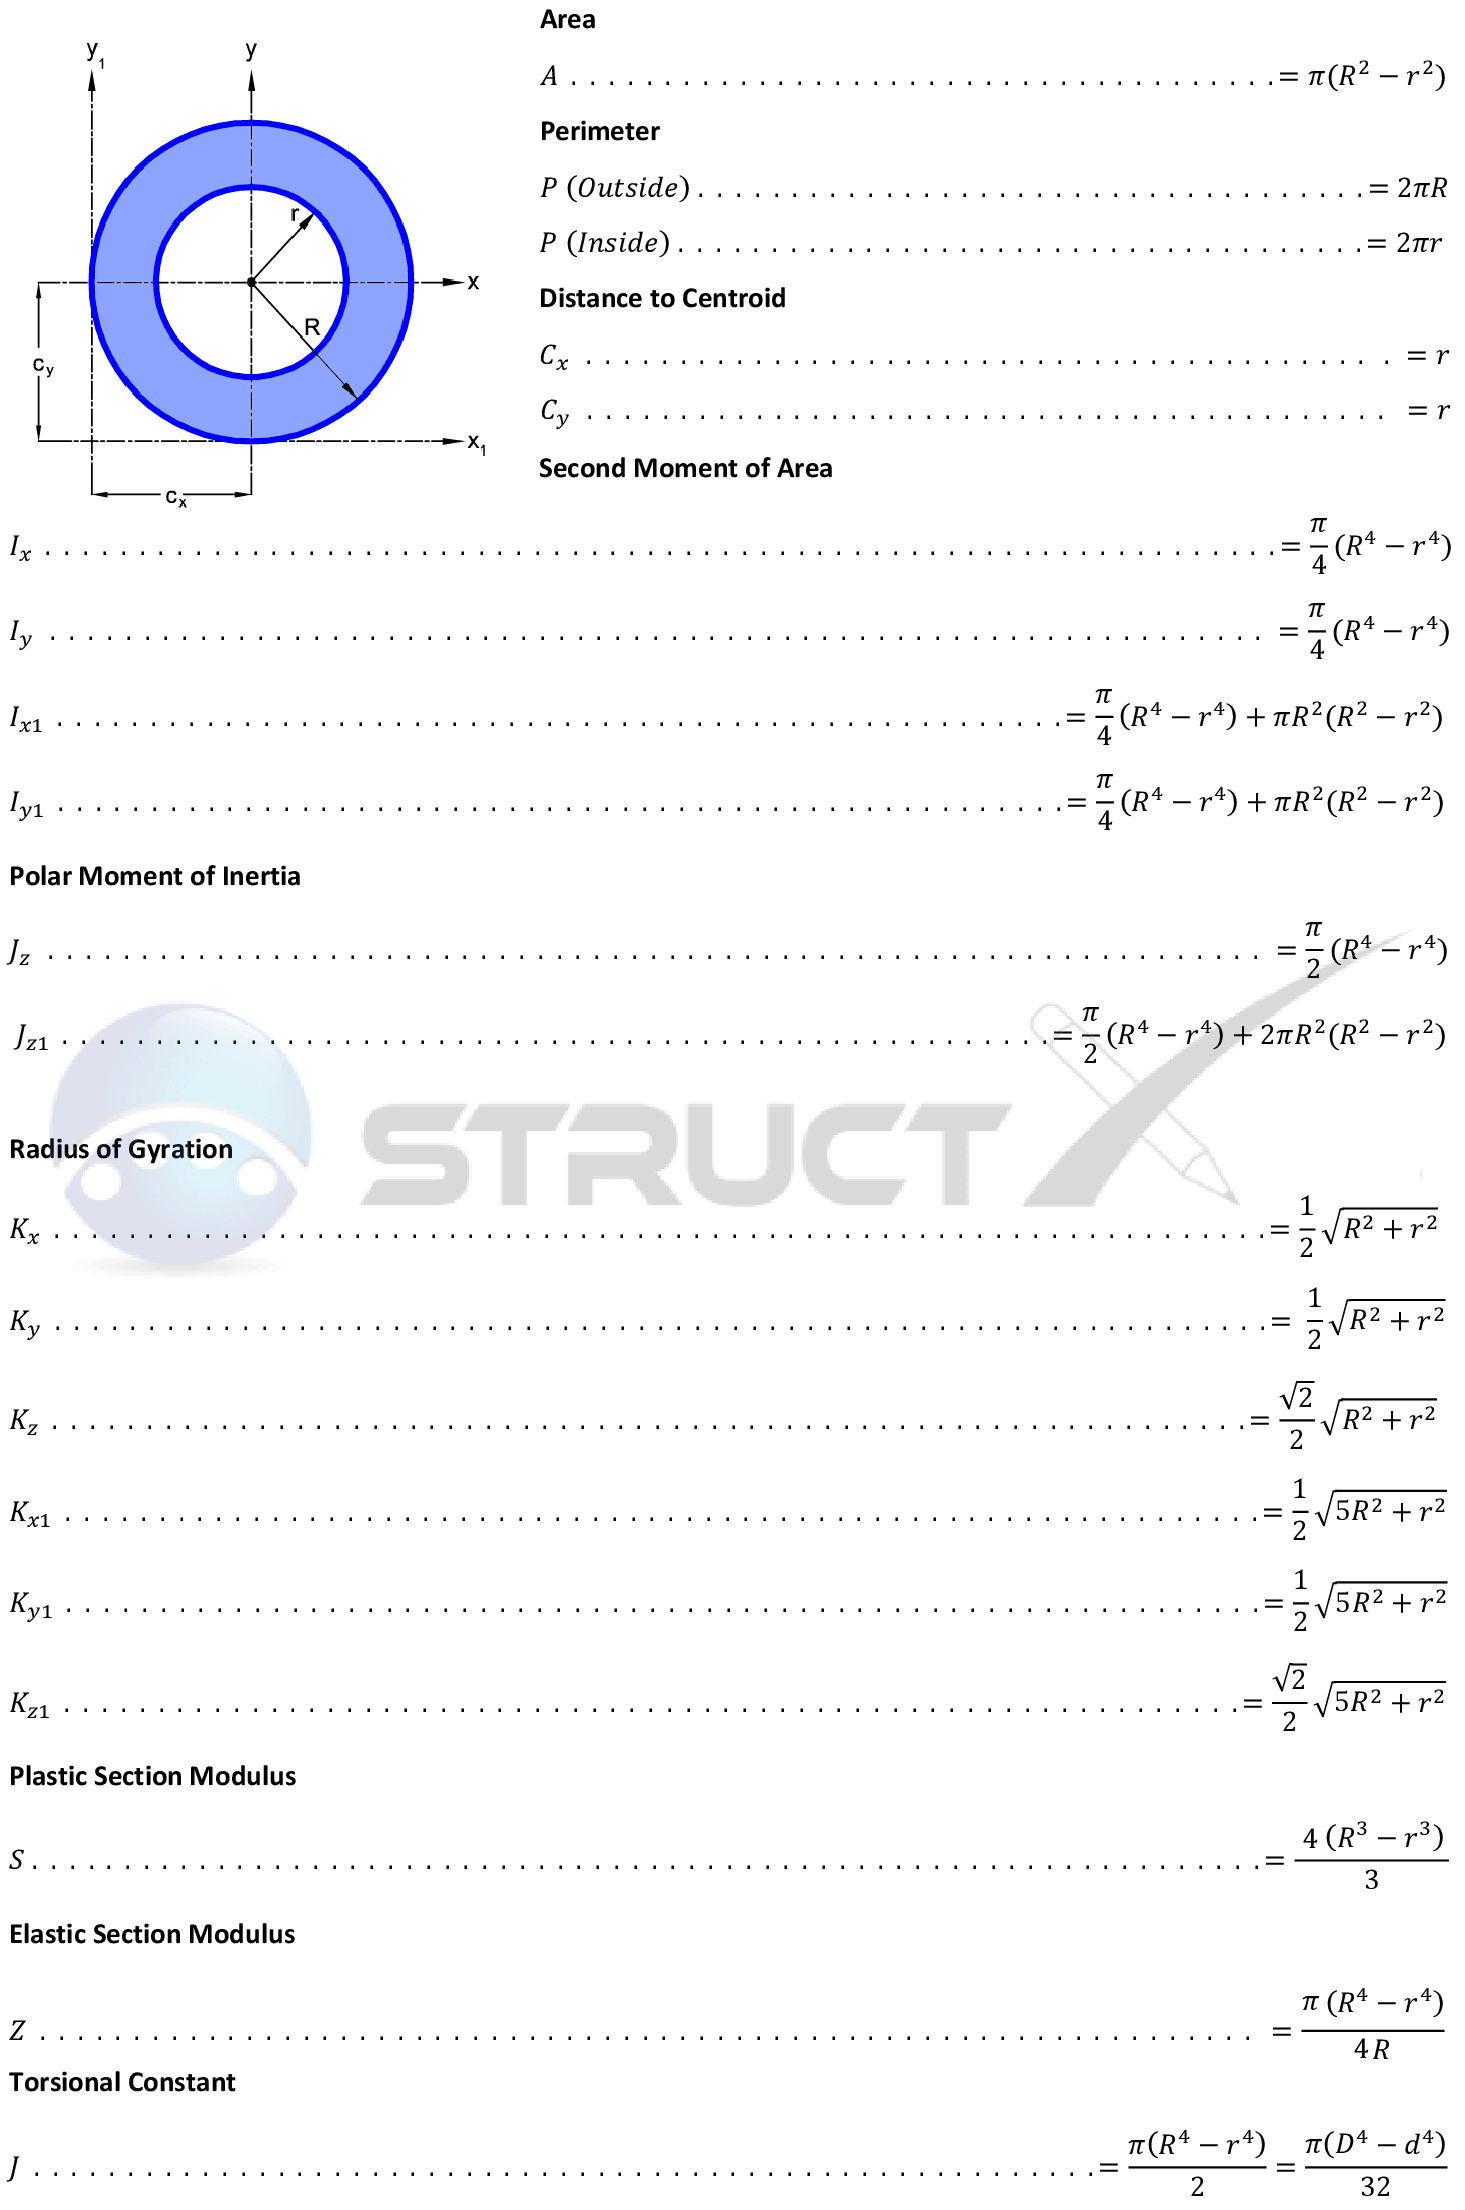

### Notation:

- A = Geometric Area, in2 or mm2

- C = Distance to Centroid, in or mm

- I = Second moment of area, in4 or mm4

- Ji = Polar Moment of Inertia, in4 or mm4, where i is x, y or z

- K = Radius of Gyration, in or mm

- P = Perimeter of shape, in or mm

- Z = Elastic Section Modulus, in3 or mm3

### Calling Sequence:

- [sectn] = sectn_circularTube(d, t)

#### Inputs:

- d - diameter outside, OD

- t - wall thickness

#### Outputs:

- sectn - sectn data structure with updated section properties

### Reference:

- https://structx.com/Shape_Formulas_014.html

function [sectn] = sectn_circularTube(d, t)
R = d/2;                                % radius outside
di = (d-2*t);                           % diameter inside
ri = di/2;                              % radius inside
sectn.type = 'circTube';                % section type
sectn.A = pi*(R^2 - r^2);               % cross-section area
sectn.P = 2*R;                          % perimeter
sectn.C1 = R;                           % distance to centroid, axis-1
sectn.C2 = R;                           % distance to centroid, axis-2
sectn.I1 = (pi/4)*(R^4 - r^4);          % area moment of inertia, axis-1
sectn.I2 = sectn.I1;                    % area moment of inertia, axis-2
sectn.Jz = 2*sectn.I1;                  % polar moment of inertia
sectn.K1 = sqrt(sectn.I1/sectn.A);      % radius of gyration, axis-1
sectn.K2 = sqrt(sectn.I2/sectn.A);      % radius of gyration, axis-2
sectn.Z1 = sectn.I1/sectn.C1;           % section modulus, axis-1
sectn.Z2 = sectn.I2/sectn.C2;           % section modulus, axis-2
sectn.J  = sectn.Jz;                    % torsional constant
end